# Classification

This example shows how to perform classification using discriminant analysis, naive Bayes classifiers, and decision trees. Suppose you have a data set containing observations with measurements on different variables (called predictors) and their known class labels. If you obtain predictor values for new observations, could you determine to which classes those observations probably belong? This is the problem of classification.

## Fisher's Iris Data

Fisher's iris data consists of measurements on the sepal length, sepal width, petal length, and petal width for 150 iris specimens. There are 50 specimens from each of three species. Load the data and see how the sepal measurements differ between species. You can use the two columns containing sepal measurements.

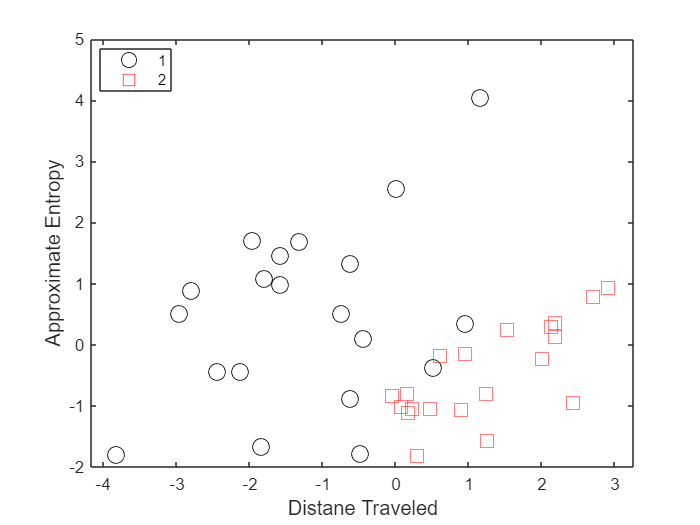

%only change the inputted data
dataa = score;

label = ground_truth;

load fisheriris
figure(1)
gscatter(dataa(:,1), dataa(:,2), label,'kr','os', 10);
xlabel('Distane Traveled', 'FontSize', 12);
ylabel('Approximate Entropy', 'FontSize', 12);

N = size(dataa,1);

Suppose you measure a sepal and petal from an iris, and you need to determine its species on the basis of those measurements. One approach to solving this problem is known as discriminant analysis.

## Linear and Quadratic Discriminant Analysis

The `fitcdiscr` function can perform classification using different types of discriminant analysis. First classify the data using the default linear discriminant analysis (LDA).

lda = fitcdiscr([dataa(:,1), dataa(:,2)],label);
ldaClass = resubPredict(lda);

The observations with known class labels are usually called the training data. Now compute the resubstitution error, which is the misclassification error (the proportion of misclassified observations) on the training set.

ldaResubErr = resubLoss(lda)

ldaResubErr = 0.1000

You can also compute the confusion matrix on the training set. A confusion matrix contains information about known class labels and predicted class labels. Generally speaking, the (i,j) element in the confusion matrix is the number of samples whose known class label is class i and whose predicted class is j. The diagonal elements represent correctly classified observations. 

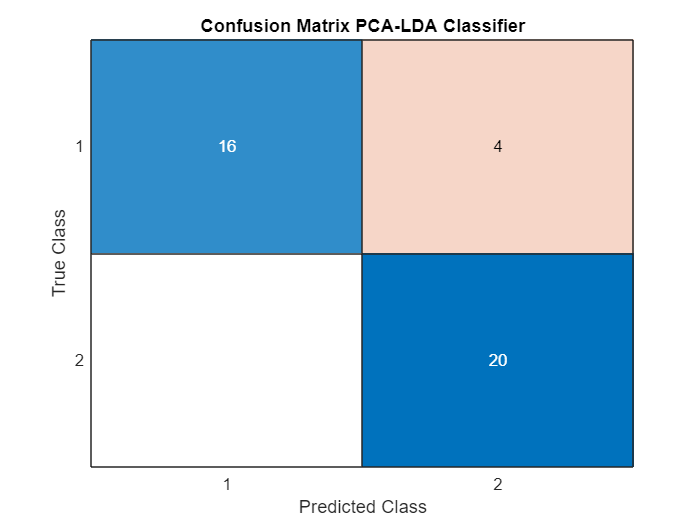


figure
ldaResubCM = confusionchart(label,ldaClass);
title('Confusion Matrix PCA-LDA Classifier')

Of the 150 training observations, 20% or 30 observations are misclassified by the linear discriminant function. You can see which ones they are by drawing X through the misclassified points.

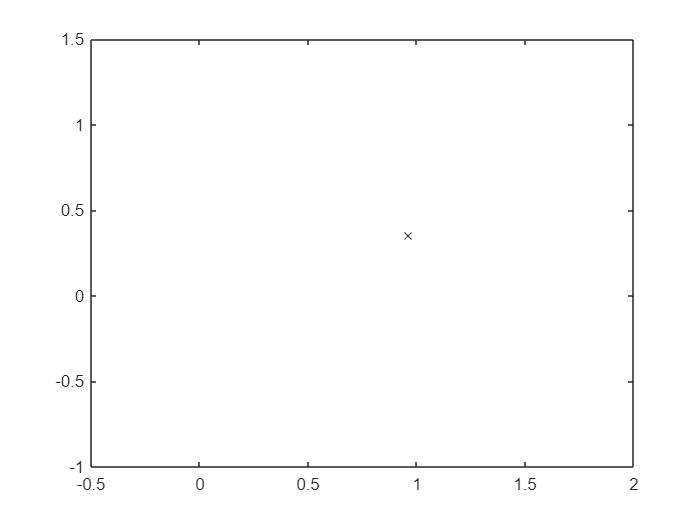

figure(2)
bad = ~strcmp(ldaClass,label);
plot(dataa(bad,1), dataa(bad,2), 'kx');
hold off;

The function has separated the plane into regions divided by lines, and assigned different regions to different species. One way to visualize these regions is to create a grid of `(x,y)` values and apply the classification function to that grid.

For some data sets, the regions for the various classes are not well separated by lines. When that is the case, linear discriminant analysis is not appropriate. Instead, you can try quadratic discriminant analysis (QDA) for our data.

Compute the resubstitution error for quadratic discriminant analysis.

mld = fitcdiscr([dataa(:,1), dataa(:,2)],label,'DiscrimType','linear');
mldResubErr = resubLoss(mld)

mldResubErr = 0.1000

cp = cvpartition(idx_pca,'KFold',10)

cp = K-fold cross validation partition
   NumObservations: 40
       NumTestSets: 10
         TrainSize: 36  36  36  36  36  36  36  36  36  36
          TestSize: 4  4  4  4  4  4  4  4  4  4

cvlda = crossval(lda,'CVPartition',cp);
ldaCVErr = kfoldLoss(cvlda)

ldaCVErr = 0.1000

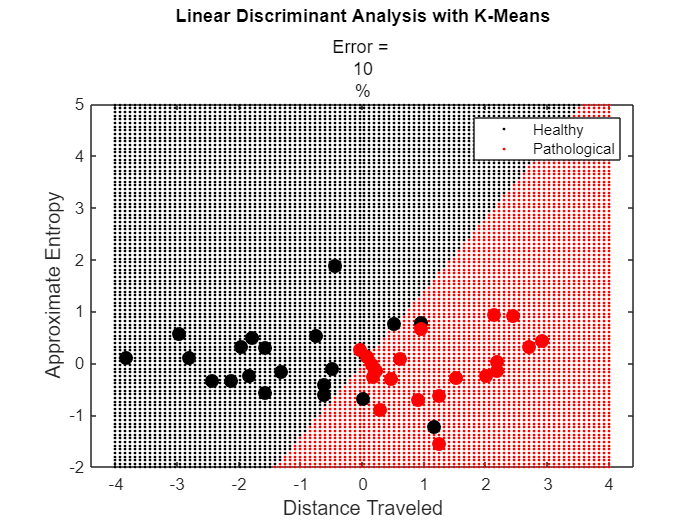



[L, W] = meshgrid(linspace(-4,4, 100), linspace(-2,5, 100));
L = L(:);
W = W(:);
pred = mld.predict([L W]);
h = gscatter(L,W,pred,'kr', '.', 1, 'off'); 
set(h, 'LineWidth', 2, 'MarkerSize', 5);
hold on;
gscatter(dataa(:,1), dataa(:,5), label,'kr','.', 25, 'off');
xlabel('Distance Traveled', 'FontSize', 12);
ylabel('Approximate Entropy', 'FontSize', 12);
legend('Healthy', 'Pathological')
title('Linear Discriminant Analysis with K-Means');
subtitle(["Error = " num2str(100*ldaCVErr) '%'])

You have computed the resubstitution error. Usually people are more interested in the test error (also referred to as generalization error), which is the expected prediction error on an independent set. In fact, the resubstitution error will likely under-estimate the test error.

In this case you don't have another labeled data set, but you can simulate one by doing cross-validation. A stratified 10-fold cross-validation is a popular choice for estimating the test error on classification algorithms. It randomly divides the training set into 10 disjoint subsets. Each subset has roughly equal size and roughly the same class proportions as in the training set. Remove one subset, train the classification model using the other nine subsets, and use the trained model to classify the removed subset. You could repeat this by removing each of the ten subsets one at a time.

Because cross-validation randomly divides data, its outcome depends on the initial random seed. To reproduce the exact results in this example, execute the following command:

rng(0,'twister');

First use `cvpartition` to generate 10 disjoint stratified subsets.

cp = cvpartition(idx_pca,'KFold',10)

cp = K-fold cross validation partition
   NumObservations: 40
       NumTestSets: 10
         TrainSize: 36  36  36  36  36  36  36  36  36  36
          TestSize: 4  4  4  4  4  4  4  4  4  4

The `crossval` and `kfoldLoss` methods can estimate the misclassification error for both LDA and QDA using the given data partition `cp`.

Estimate the true test error for LDA using 10-fold stratified cross-validation.

cvlda = crossval(lda,'CVPartition',cp);
ldaCVErr = kfoldLoss(cvlda)

ldaCVErr = 0.1000

The LDA cross-validation error has the same value as the LDA resubstitution error on this data.

Estimate the true test error for QDA using 10-fold stratified cross-validation.

cvqda = crossval(lda,'CVPartition',cp);
qdaCVErr = kfoldLoss(cvqda)

qdaCVErr = 0.1000

[L, W] = meshgrid(linspace(4.5,8))

L =     4.5000    4.5354    4.5707    4.6061    4.6414    4.6768    4.7121    4.7475    4.7828    4.8182    4.8535    4.8889    4.9242    4.9596    4.9949    5.0303    5.0657    5.1010    5.1364    5.1717    5.2071    5.2424    5.2778    5.3131    5.3485    5.3838    5.4192    5.4545    5.4899    5.5253    5.5606    5.5960    5.6313    5.6667    5.7020    5.7374    5.7727    5.8081    5.8434    5.8788    5.9141    5.9495    5.9848    6.0202    6.0556    6.0909    6.1263    6.1616    6.1970    6.2323
    4.5000    4.5354    4.5707    4.6061    4.6414    4.6768    4.7121    4.7475    4.7828    4.8182    4.8535    4.8889    4.9242    4.9596    4.9949    5.0303    5.0657    5.1010    5.1364    5.1717    5.2071    5.2424    5.2778    5.3131    5.3485    5.3838    5.4192    5.4545    5.4899    5.5253    5.5606    5.5960    5.6313    5.6667    5.7020    5.7374    5.7727    5.8081    5.8434    5.8788    5.9141    5.9495    5.9848    6.0202    6.0556    6.0909    6.1263    6.1616    6.1970    6

W =     4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000    4.5000
    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4.5354    4

## Conclusions

This example shows how to perform classification in MATLAB® using Statistics and Machine Learning Toolbox™ functions.

This example is not meant to be an ideal analysis of the Fisher iris data, In fact, using the petal measurements instead of, or in addition to, the sepal measurements may lead to better classification. Also, this example is not meant to compare the strengths and weaknesses of different classification algorithms. You may find it instructive to perform the analysis on other data sets and compare different algorithms. There are also Toolbox functions that implement other classification algorithms. For instance, you can use `TreeBagger` to perform bootstrap aggregation for an ensemble of decision trees, as described in the example [Classifying Radar Returns for Ionosphere Data](docid:stats_ug.mw_e87245e6-e9ea-4033-b985-3ae52cb2b963).

*Copyright 2002-2014 The MathWorks, Inc.*